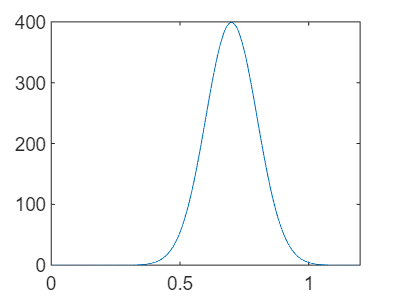

clc;clear;
wl = linspace(0,1.2,1024);
gv1 = 100;
sigma1 = 0.1;
u1 = 0.7;
guass1 = guassf(wl,gv1,sigma1,u1);
plot(wl,guass1)

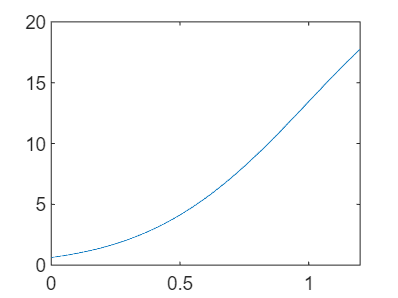

gv2 = gv1/3;
fwhm = zeros(50,100);    %fwhm = zeros(1000,2000);
ccwl = zeros(50,100);    %ccwl = zeros(1000,2000);
for n = 1:500      %for n = 1:1000
sigma2 = n*0.001+0.1;   %sigma2 = n*0.0005+0.2;
for i = 1:100      %for i = 1:2000
   u2 = i*0.02-0.4;     %u2 = i*0.001-0.4;
   guass2 = guassf(wl,gv2,sigma2,u2); 
   guass3 = guass1 + guass2;
   fwhm(n,i) = fwhmf(wl,guass3); 
   ccwl(n,i) = ccwlf(wl,guass3);
end
end

plot(wl,guass2)

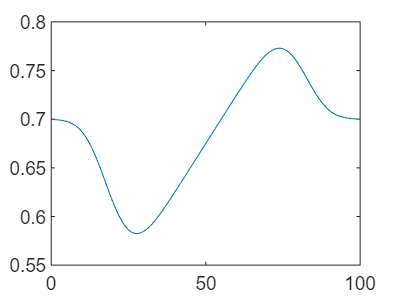

figure(1)
% for i = 1:5
   plot(ccwl(30,:));

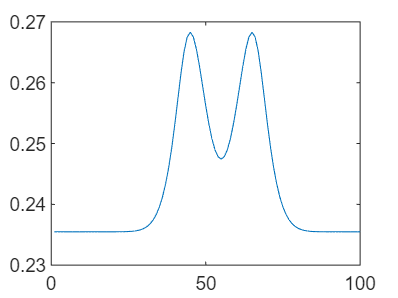

%    hold on
% end
% hold off
figure(2)
% for i = 1:5
   plot(fwhm(30,:));

%    hold on
% end
% ccwl1 = ccwlf(wl,guass1)
% fwhm = fwhmf(wl,guass1)
x = 1:100;
ccwl2 = ccwl(30,:);
fwhm2 = fwhm(30,:);
idx = find(diff(sign(ccwl2-0.65)))

idx =     15    44


ccwl2(idx)

ans =     0.6568    0.6450


fwhm2(idx)

ans =     0.2355    0.2675


function guass = guassf(wl,gv,sigma,u)
guass = gv/(sigma*sqrt(2*pi))*exp(-(wl-u).^2/(2*sigma^2));
end

function fwhm = fwhmf(wl,guass)
pks = max(guass);
idx = find(diff(sign(guass-pks/2)));
fwhmn = zeros(2,1);
for i = 1:numel(idx)
    x = wl(idx(i)-2:idx(i)+2);
    y = guass(idx(i)-2:idx(i)+2);
    fwhmn(i,:) = interp1(y,x,pks/2,'pchip');
end
fwhm = diff(fwhmn);
end

function ccwl1 = ccwlf(wl,guass)
P = sum(wl.*guass);
Q = sum(guass);
ccwl1 = P/Q;
end